# `智能控制 课程考查`

# `Indirect Model Reference Aapative RBF Control —— `

# `Initial Parameters Optimized by Generic Algthorim `

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.19）

% 这里的控制思想是？ 前馈控制器(NN逼近器)去逼近被控对象的逆 嘛
% 调整了u的位置，方便理解
% 需寻优参数  bj->[当前0.5]   cScar->[当前4]  w->[当前0.1]       采样需1024*32确保结果是稳定的

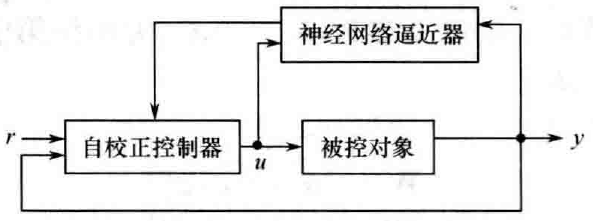

% Self-Correct control based RBF Identification
clear all;
clc;
close all;
load BestS_WillWatson.mat; 

SampleN = 1024*8 ; % index
TimeStamp = zeros(1,SampleN); % Specific Time
ts = 0.02;  % 50 Hz
 
neuroN = 6; % Even better
Array = 1:1: neuroN/2;

xite1 =0.15;
alfa  =0.07;

% bj = [0.603030303030303	0.576832844574780	0.343401759530792	0.532258064516129	0.325024437927664	0.459530791788856	0.447800586510264	0.633528836754643	0.608113391984360	0.694916911045943	0.583088954056696	0.637047898338221]'; % colum
% cij = [2.72531769305963	-3.08504398826979	2.61583577712610	-2.20136852394917	-1.02834799608993	-1.70087976539589	-2.87390029325513	-1.91984359726295	-1.25513196480938	-3.98435972629521	2.16226783968719	2.65493646138807] ;  % row
% w =  [-0.254838709677419	0.224340175953079	-0.263049853372434	0.00615835777126100	-0.223167155425220	-0.0782991202346041	0.0343108504398827	0.0900293255131965	0.223753665689150	-0.292961876832845	-0.171554252199413	-0.266568914956012]'; % colum

bj = (p(:,1:neuroN))';   % colum
cij = p(:,(neuroN+1):2*neuroN) ;   % row
w =  (p(:,(2*neuroN+1):3*neuroN))'; % colum

% bj =  p(1)*ones(neuroN,1) ; 
% cScar = 1/(neuroN/2)*p(2);
%     cij = [-sort(Array,'descend')*cScar  sort(Array)*cScar];
% w = [p(3);p(4);p(5);p(6);p(7);p(8);p(9);p(10);p(11);p(12);p(13);p(14);];

w_1=w; w_2=w_1; 
;
r = zeros(1,SampleN);
u = zeros(1,SampleN); u_1=0;
y = zeros(1,SampleN); y_1=0; ym = zeros(1,SampleN);
h = zeros(neuroN,1);
g = zeros(1,SampleN);  Ng = zeros(1,SampleN);
e = zeros(1,SampleN);


$$r_k$$


 
$$y_k =\psi \left(y_{k-1,} \;u_{k-1} \right)\;\;$$
  


$$N_{g\;k} =\xi \left(y_k ,w_{k-1} \;\right)$$
   


$$N_{f\;k} =\zeta \left(y_k ,v_{k-1} \;\right)$$
    


$$u_k =\Phi \left(N_{g\;k} ,\;N_{f\;k} ,r_k \;\right)$$
  

————————————————

$y_{m\;\;k} =\Theta \left(N_{g\;k} ,\;N_{f\;k} ,\;u_{k-1} \;\right)$  当次预估输出 

$e_k =y_k -y_{m\;\;k}$     最主要是核对error的含义


$$w_k =\Gamma \left(e_k ,{\;w}_{k-1,} {\;\;w}_{k-2} ,\;\alpha ,{\;\eta }_1 \right)$$
 


$$v_k =Z\left(e_k ,{\;v}_{k-1,} {\;\;v}_{k-2} ,\;\alpha ,\;\eta_2 ,{\;u}_{k-1} \;\right)$$
 

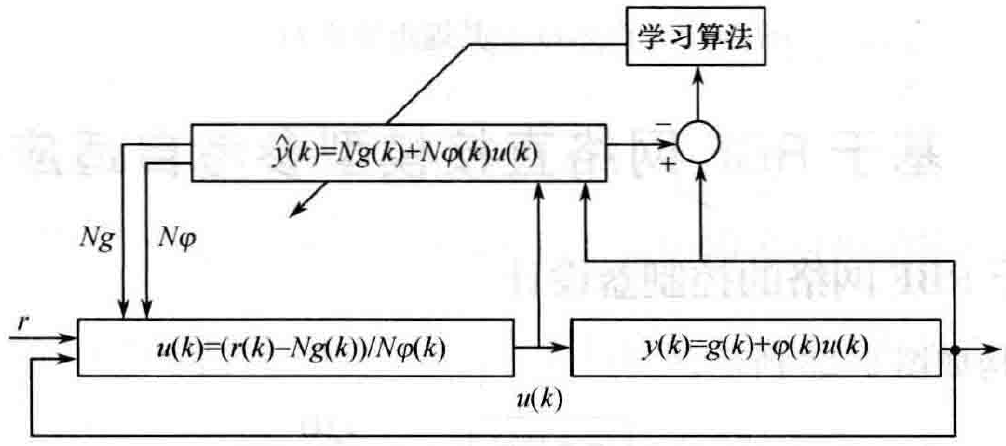

for k=1:1:SampleN
    TimeStamp(k) = k*ts;
   r(k) = sin(2*pi*k*ts/25) + sin(2*pi*k*ts/10);  
    
 %Practical Plant; %  Test for Job9_2
 
    y(k) = 0.8*y_1/(1+y_1^2) + u_1^3;
    g(k) = 0.8*y_1/(1+y_1^2);
     
    for j=1:1:neuroN
        h(j) = exp( -norm(y(k)-cij(:,j))^2 / (2*bj(j)*bj(j)) );
    end
    
    Ng(k) = w_1'*h;
    
    if (-Ng(k)+r(k)) >0
        u(k) = (-Ng(k)+r(k))^(1/3);
    else
        u(k) = -(abs(-Ng(k)+r(k)))^(1/3);
    end

%     u(k) = (r(k)-Ng(k))^(1/3) ;
    
    ym(k) = Ng(k) + u_1^3; % hat
 
    %————————————————————   ———————————————————————
    e(k) = y(k)-ym(k);
 
    d_w = 0*w;
    for j=1:1:neuroN
        d_w(j) = xite1 * e(k) * h(j);
    end
    w = w_1 + d_w + alfa*(w_1-w_2);
 
    %———————————————————— Exit Update ———————————————————————
    u_1 =u(k);
    y_1 =y(k);
    w_2=w_1;  w_1=w;
 end

cij

cij =    -0.3006    3.0718    2.5733   -5.3739    2.9252   -2.1628


bj

bj =     6.4946
    8.0000
    1.9238
    7.0215
    5.5709
    6.2414


w

w =     0.0635
    0.3602
    0.7055
   -0.5081
   -0.0421
   -0.1162


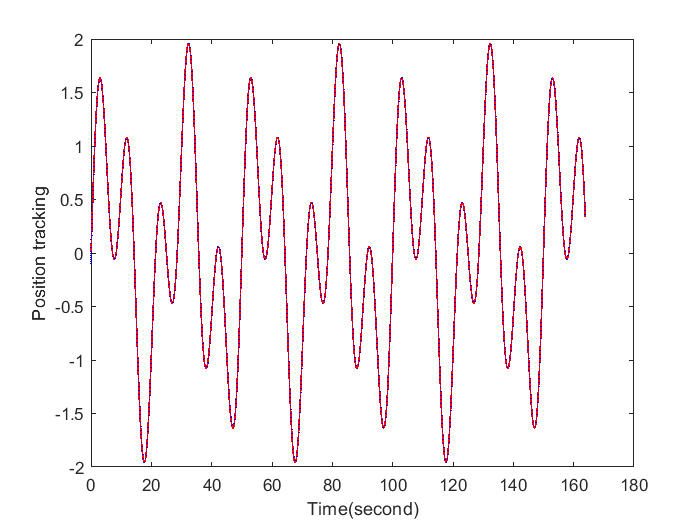

figure(1);
plot(TimeStamp,r,'r' ,TimeStamp,y,'b:','linewidth',1);
% ,TimeStamp,y,'b:'
xlabel('Time(second)');ylabel('Position tracking');

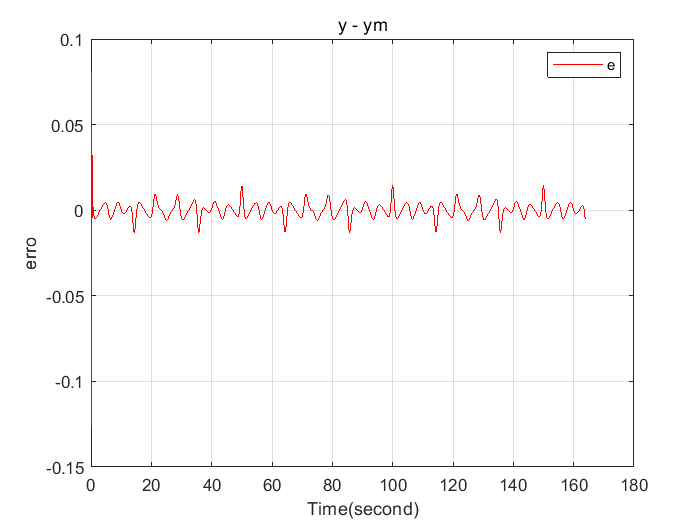

figure(2);
plot(TimeStamp,e,'r');
legend('e');
title('y - ym')
xlabel('Time(second)');ylabel('erro');
grid on

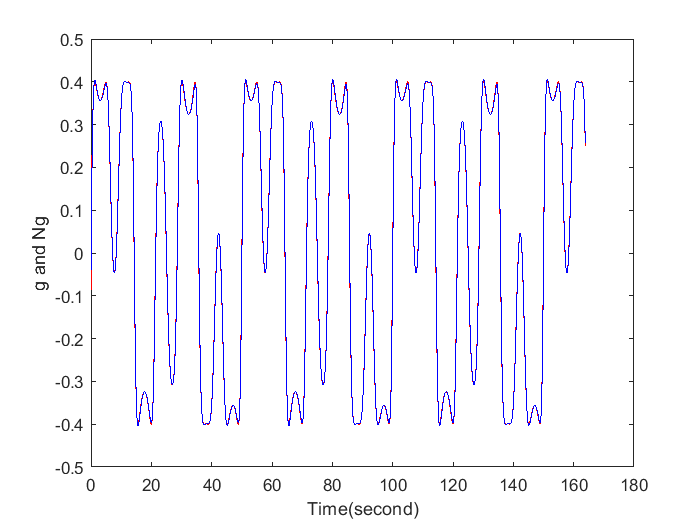

figure(3);
plot(TimeStamp,g,'r',TimeStamp,Ng,'b'); % 
xlabel('Time(second)');ylabel('g and Ng');